# DISPOSITIVO 1

### PROTOCOLLO DI COMUNICAZIONE DI DISPOSITIVO 1

- Trasmissione di numFrames simboli per numRip volte

- Si mette in attesa di ricezione per waitTime secondi

- Ricomincia la trasmissione

- Se non riceve riscontro per numAtteseMax volte, il dispositivo inivia un 'Keep Alive'. Se non riceve risposta, termina la trasmissione

### SETUP INIZIALE DI TX E RX

addpath '/home/nicola-gallucci/Nicola/Matlab/ProgettoSistemi/plutoTest/provaModulazione/DISPOSITIVO1/TransmitterCodifica'
[OFDMParams,dataParams, GeneralParam] = helperSetParameters();
attese = 0;

### TRASMISSIONE

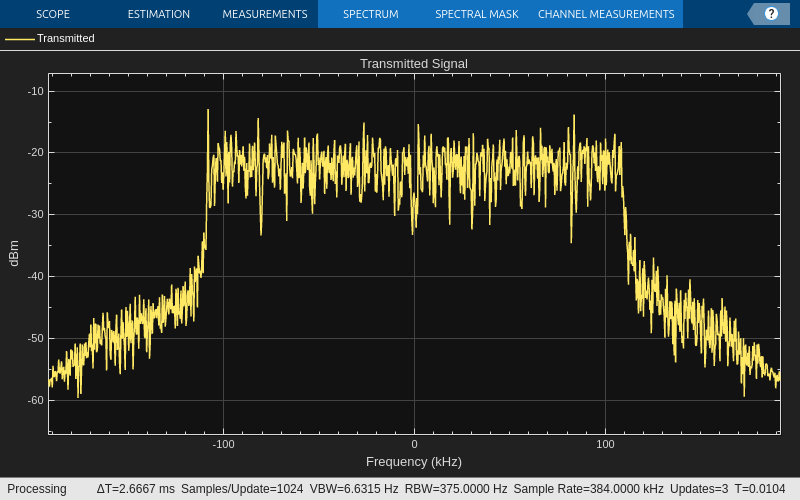

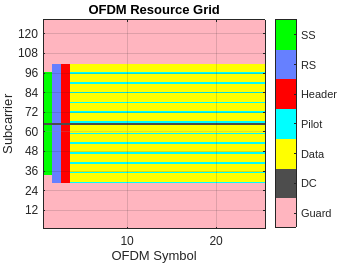

[radio, txWaveform, sysParam, tunderrun] = transmissionCode(GeneralParam, OFDMParams,dataParams);

for ii = 1:numRip
    helperRadioTx(txWaveform,sysParam, radio, tunderrun);
    pause(2);
end

## Establishing connection to hardware. This process can take several seconds.


% Clean up the radio System object
    release(radio);

### ATTESA RICEZIONE

if attese ~= GeneralParam.numAtteseMax 
else

end